%{
Bisection method is basically like binary search. We are provided with a
interval [a,b] and we half the interval at every iteration. We first check
if f(a) * f(b) < 0. if it is less than zero, we know that the root is
within the interval. If it is not we know that the root is not in the
interval and bisection will not work. After this check, we find the
midpoint and calculate f(midpoint) and see which half the root is in by
finding out which half is negative. i
%}




%constants and args needed for function
MAX_ITERATIONS = 100;
ACCURACY = 10^-6; %coding test question3: changed tolerance to 10^-6
START = -3; %coding test question1: changed start to -3
END = 0; %coding test question1: changed end to 0

%our function for the problem
%f = @(x) (2*x.^3+3*x-1).*cos(x)-x; %question 6 commented out old function
f = @(x) cos(sin(x.^2 - 1).^2) - .65;%question 6 added new function 
%c is root, n is num_iterations, err is error bound
[c,n,err] = bisection_method(f,START,END,ACCURACY,MAX_ITERATIONS)

c = -1.4432

n = 22

err = 7.1526e-07

disp(['Root: ', num2str(c)]);

Root: -1.4432


disp(['Iterations: ', num2str(n)]); %coding test question2 / question4/7: didnt change anything but this is where it shows the # of iterations

Iterations: 22


disp(['Error: ', num2str(err)]);

Error: 7.1526e-07


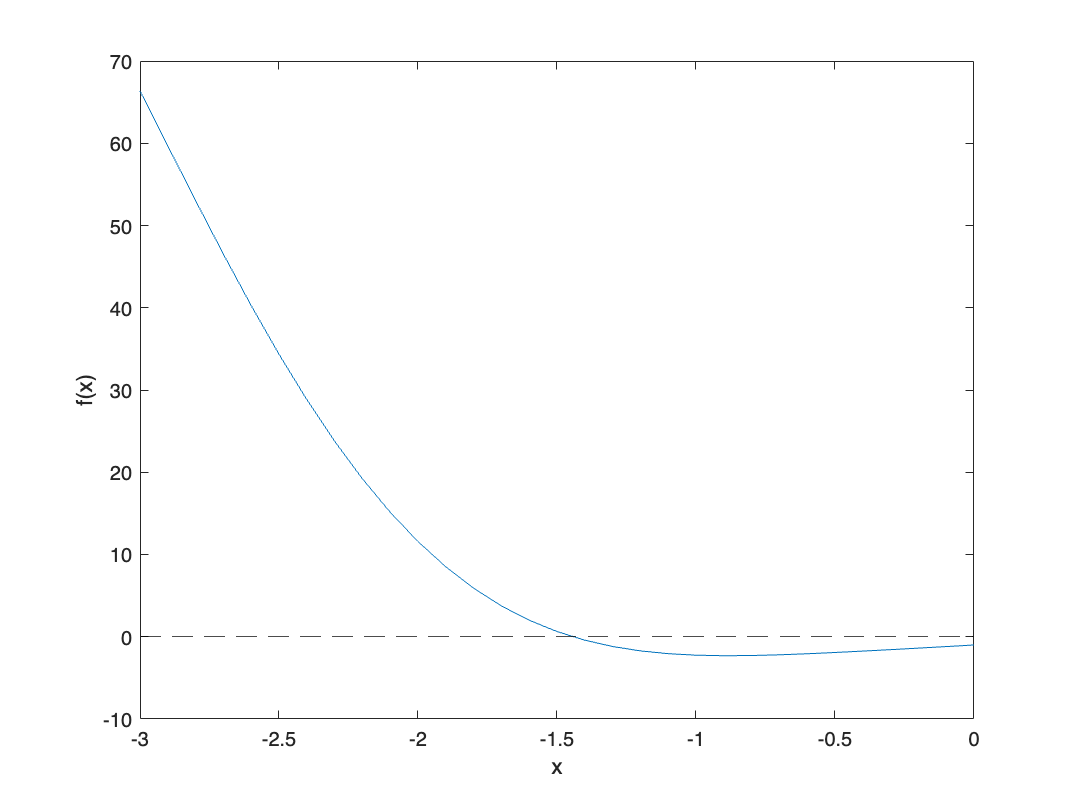

%root = solve(f == 0)

function [c,n,err] = bisection_method(f,a,b,tol,N)
     
    %root is not in bound
    if f(a) * f(b) > 0
        error("root not bound by [a,b]")
    end

    %n is the counter for the number of iterations
    n = 0;
    %err is the inital error
    err = abs(b - a);

    %if error is less than the tolerance we have found an acceptable value
    %if n is greater than N we have surpassed the max number of iterations

    while err > tol && n < N

        %c is the middle of a and b
        c = (a + b)/2;
        
        %if f(c) is zero we have found a root
        fc = f(c);
        if fc == 0
            err = 0;
            return;
        else
            %to check which half of the interval contains the root
            if f(a) * f(c) < 0
                %we set b to be middle and now [a,b] will be the left half
                b = c;
            else
                %we set a to be the middle so [a,b] is the right half
                a = c;
            end
        end
        
        %update error and iterations
        err = abs(b - a);
        n = n + 1;
    end
     %in case we do not converge, we do this to find the best estimate of
     %the root
     c = (a + b)/2;
end


%plot
x = START:0.1:END;  % Generate x values from -10 to 10 with a step size of 0.1
y = f(x);        % Evaluate the function at those x values
plot(x, y)
hold on

yline(0, '--k');
xlabel('x');
ylabel('f(x)');

% title('Plot of f(x) = (x^2 + 3x + 2)cos(x)-x');

%extra credit attempt
%{
formula would be 
n = logbase2((b-a)/(cn - c))
%}